# DSP Lab 03

# Processing of 2D Signals (Images)

## 1. Objective

Students should understand and be able to operate with 2D data (images).

## 2. Theoretical aspects

### 2. 1 Images as matrices

A **grayscale image** can be regarded as a matrix. Each pixel corresponds to one value in the matrix. The value of an element in the matrix gives the shade of the pixel:

- 0 means pixel is black

- 1 (or 255) means pixel is white

- a value between 0 and 1 means a corresponding shade of gray between black and white

**Note:** the maximum value can be either 1 or 255, depending on the convention used.

A **color image** has three values for a pixel: (R,G,B), meaning Red component, Green component and Blue component. Any color can be obtained by mixing appropriate amounts of Red, Greed and Blue.

A color image in Matlab can be represented in multiple ways. The easiest way is to consider a multidimensional array ("**tensor"**) of size (H, W, 3). A value situated at position (row, column, color) indicates the RGB component for the pixel at the specified row and column.

For example, M(5, 15, 3) is the Blue component (3rd) for the pixel at row 5 and column 15.

A color image can be also represented as three separate matrices, the first holding the R values for all the pixels, the second matrix holding the G's, anf the third the B's.

### 2.2 Matlab functions for image handling

In Matlab, we read an image file with `imread()`. 

We can display a matrix as an image with `imshow()`. 

We save an image to disk with `imwrite()`. 

If the matrix contains integer values going to 255 (check this in the Workspace), it is typical to convert the values to double and divide them to 255, so that all the values will be floating-point numbers between 0 and 1.

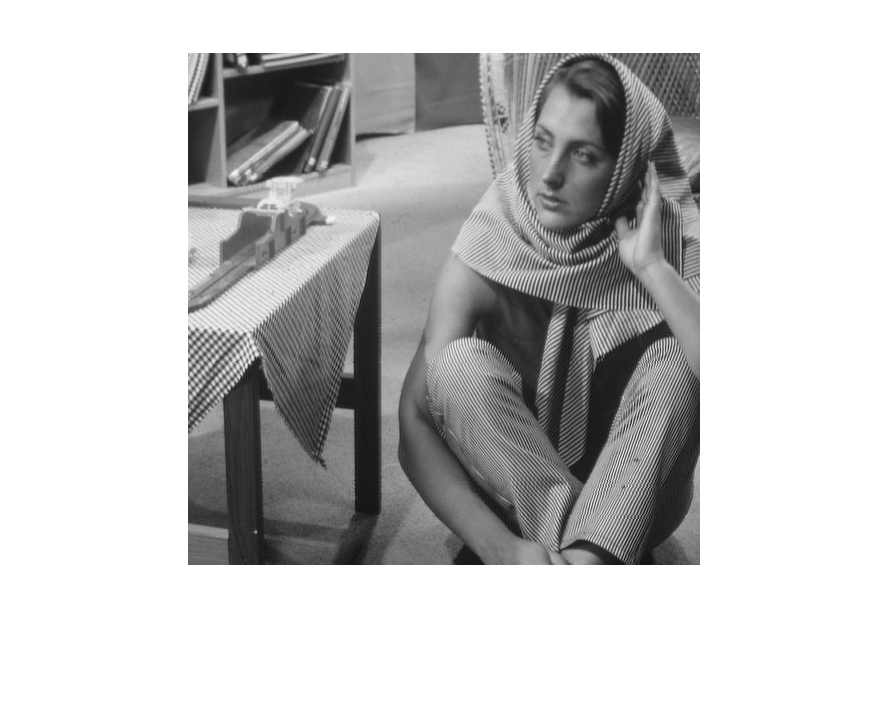

% Load a grayscale image 
I = imread('barbara.png');

% Convert values to double and divide by 255
I = double(I)/255;

% Display the image
imshow(I)

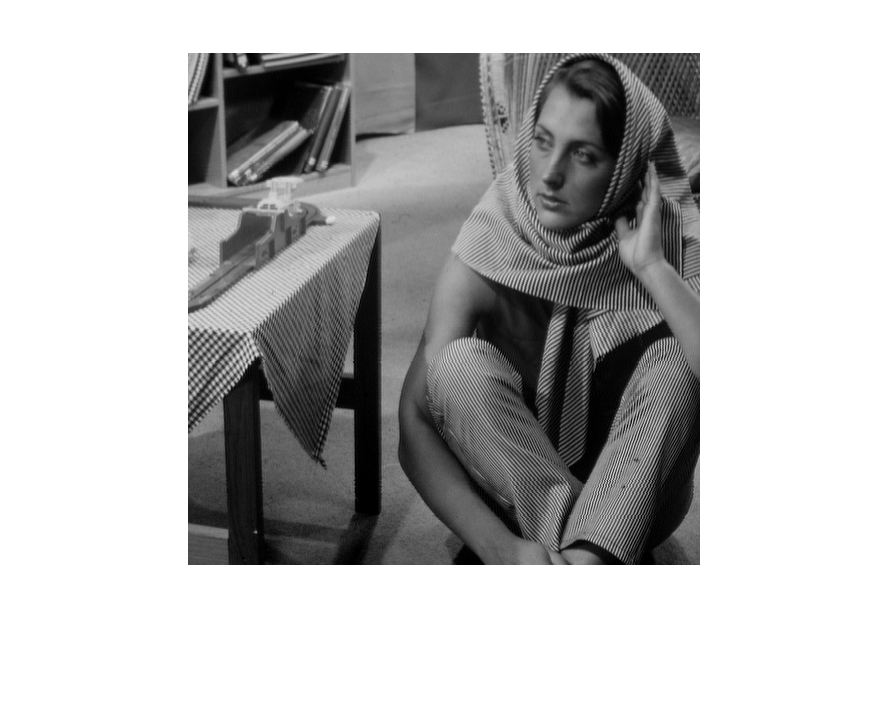


% Darken the image by subtracting 0.1 from all pixels
I2 = I - 0.1;  % I2 is still a matrix

% Display the new image
figure
imshow(I2)


% Write modified image to disk
imwrite(I2, 'barbara_modif.png')

### 2.3 Concatenate in any dimension

The Matlab function `cat()` does concatenation of arrays along any specified direction.

A = rand(2,3);
B = rand(2,3);
C1 = cat(1,A,B);  % Concatenate across first dimension => size is (4,3)
size(C1)

ans =      4     3


C2 = cat(2,A,B);  % Concatenate across second dimension => size is (2,6)
size(C2)

ans =      2     6


C3 = cat(3,A,B);  % Concatenate across third dimension => size is (2,3,2)
size(C3)

ans =      2     3     2


## 3. Exercises

1. Create and display a chessboard image with each square having size $5 \times 5$ pixels.

2. Modify the chessboard image to have light gray and dark gray instead of white and black.

3. Create a $200 \times 300$ color image representing the Romanian flag (3 stripes of blue, yellow, red). Create the image using the following steps:

- Create three matrices for the R, G, B components of the image

- Concatenate the three matrices across third dimension, into a 3D tensor

4. Load the `Lena512.bmp` image and display it.

5. Construct a new image based on the `Lena`, but in which each pixel value is set as a linear combination of the original pixels around it, as in the following equation. Ignore the first and last row/column (it makes life simpler here). Display the resulting image. How did it change?


$$y[i,j] = \frac{1}{9}x[i-1,j-1] + \frac{1}{9}x[i-1,j] + \frac{1}{9}x[i-1,j+1] \\
        +\frac{1}{9}x[i,j-1]   + \frac{1}{9}x[i,j]   + \frac{1}{9}x[i,j+1] \\
        +\frac{1}{9}x[i+1,j-1] + \frac{1}{9}x[i+1,j] + \frac{1}{9}x[i+1,j+1]$$


6. Repeat Exercise 2 but change the values of the coefficients used in the equation to the following:


$$\pmatrix{ 0 & -1 & 0 \cr  -1 & 5 & -1 \cr  0 & -1 & 0}
$$


7. Repeat Exercise 2 but change the values of the coefficients to


$$$\pmatrix{
 0 & -1 & 0 \cr
 -1 & 5 & -1 \cr
 0 & -1 & 0}$$$


8. Repeat Exercise 2 but change the values of the coefficients to


$$$
\pmatrix{
 -1 & -1 & -1 \cr
 -1 & 8 & -1 \cr
 -1 & -1 & -1
}
$$$


9. Repeat Exercise 2 but change the values of the coefficients to


$$$
\pmatrix{
 0 & -1 & -0\cr
 -1 & 4 & -1 \cr
0 & -1 & 0
}
$$$


## 4. Final questions

1. TBD